addpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\matlab\functions\");
addpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\legacy\DataAnalysis\");
addpath("C:\Users\agori\Downloads\filesfromfriday\");

[arrClouds, fnames] = readPlyGroup('ply\');

% arrTest = arrClouds(1:10);

% [arrMarkers, fmarkers] = readPlyGroup('testMarkers\');

arrTest =   1×10 pointCloud array with properties:

    Location
    Count
    XLimits
    YLimits
    ZLimits
    Color
    Normal
    Intensity


% %pcDisplay(arrMarkers(1))
% %fnamesTest = fnames(1:10);


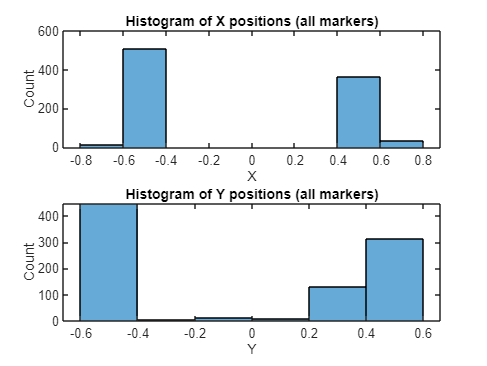

z_roi = [-inf, inf];

y_roi = [-0.4, 0.4];
x_roi = [-0.4, 0.4];

roi=[x_roi,y_roi,z_roi];
arrCropClouds = cropClouds(arrClouds, roi);

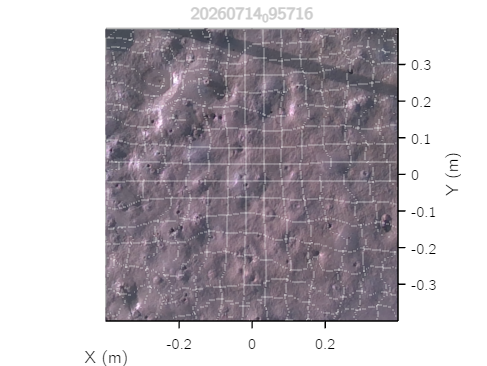

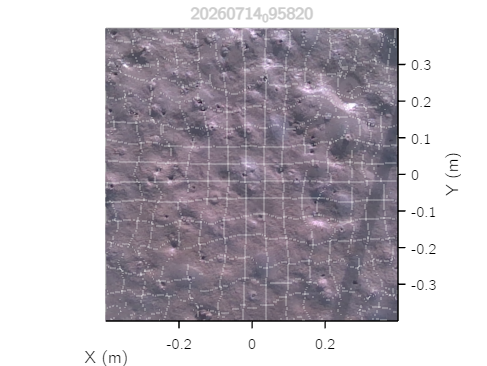

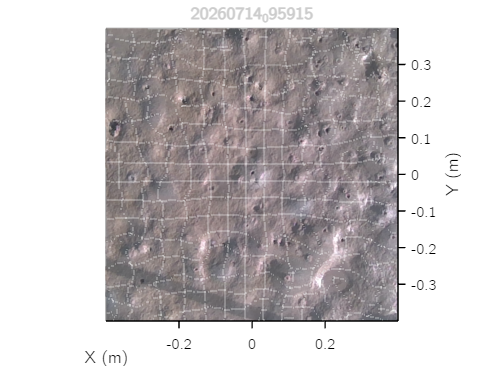

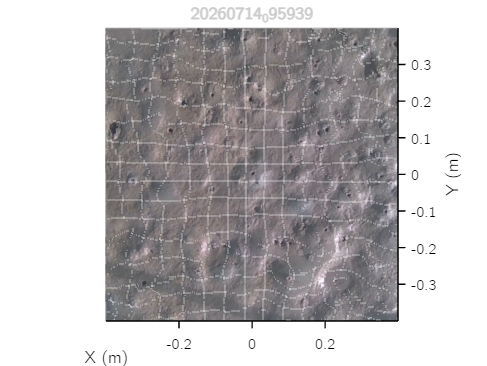

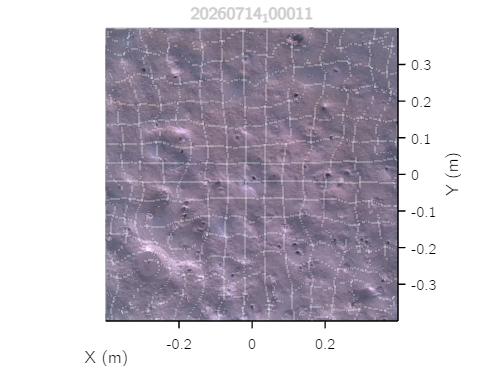

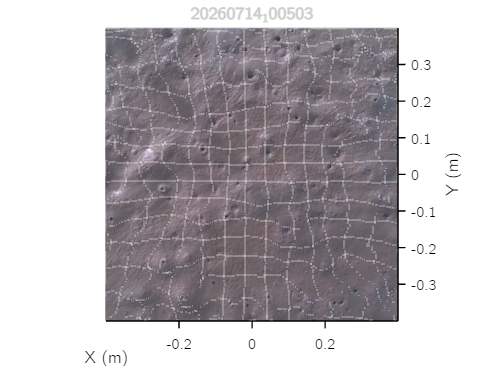

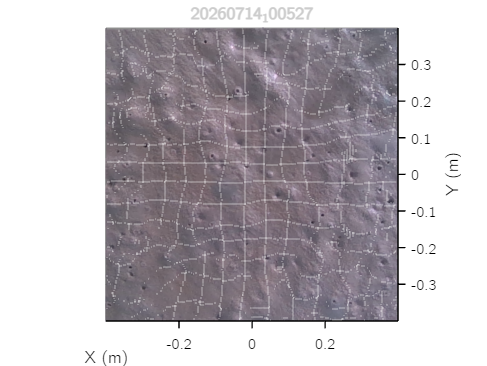

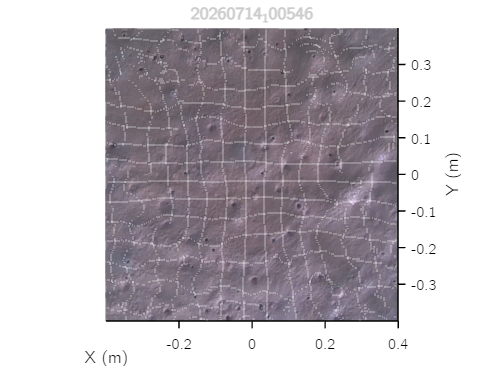

outputDir = 'outputFiles/output_RGB';
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

numClouds = length(arrCropClouds);
%Display all clouds with image color
for i = 1:numClouds
    figure;
    pcDisplay(arrCropClouds(i));
    [~, fig_name, ~] = fileparts(fnames(i));
    title(fig_name);
    fig_name =fig_name + "_RGB" + ".png";
    view(2);
    saveas(gcf, fullfile(outputDir, fig_name))
end

outputDir = 'outputFiles/output_RGBfull';
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

numClouds = length(arrCropClouds);
%Display all clouds with image color
for i = 1:numClouds
    fig = figure('Visible', 'off');
    pcDisplay(arrClouds(i));
    [~, fig_name, ~] = fileparts(fnames(i));
    title(fig_name);
    fig_name =fig_name + "_RGBfull" + ".png";
    view(2);
    saveas(fig, fullfile(outputDir, fig_name))
    close(fig);
end

outputDir = 'outputFiles/output_Clouds';
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end
% Compute global Z range across all clouds for colouring
% globalZMin = Inf;
% globalZMax = -Inf;
% for i = 1:numClouds
%     z = arrCropClouds(i).Location(:, 3);
%     globalZMin = min(globalZMin, min(z));
%     globalZMax = max(globalZMax, max(z));
% end
% globalZMin = -1;
% globalZMax = -0.5;
% %Display all clouds with color range
for i = 1:numClouds
    %figure;
    fig = figure('Visible', 'off');

    pcDisplay(arrCropClouds(i).Location);
    %clim([globalZMin, globalZMax]);   % enforce uniform colorbar
    view(2);
    c = colorbar('southoutside');
    c.Label.String = 'Z (m)';
    [~, fig_name, ~] = fileparts(fnames(i));
    title(fig_name);
    fig_name =fig_name + "_Cloud" + ".png";
    view(2);
    saveas(fig, fullfile(outputDir, fig_name))
    close(fig);
end

addpath('C:\Users\agori\Documents\MSc 2022\Landy code\Surface Roughness\Surface Roughness')

numClouds=length(arrCropClouds);
F_all = cell(1, numClouds);
X_all = cell(1, numClouds);
Y_all = cell(1, numClouds);
numClouds = length(arrCropClouds);
for i = 1:numClouds
    %pcNew = A_clouds(i);
    pcNew = arrCropClouds(i);
    x = double(pcNew.Location(:,1));
    y = double(pcNew.Location(:,2));
    f = double(pcNew.Location(:,3));
    scale = 0.005;
    [X_landy,Y_landy,F_landy] = linear_interp(x,y,f,scale);
    F_all{i} = F_landy; 
    Y_all{i} = Y_landy; 
    X_all{i} = X_landy;
    %surf(X_landy, Y_landy, F_landy, 'EdgeColor', 'none');
    %view(2)
end


% Pre-allocate
varNames = {'Filename','Mean','Median','STD','MAD','Skewness','Kurtosis', 'Rugosity'};
results = table('Size', [numClouds, 8], ...
                'VariableTypes', {'string','double','double','double','double','double','double', 'double'}, ...
                'VariableNames', varNames);

for i = 1:numClouds
    %[F, X, Y] = interpolateCloud(arrCropClouds(i), 0.01);
    %F_cur = F
    F_cur = F_all{i};
    Fclean = F_cur(~isnan(F_cur));

%Uncomment for normalized
%     R = F_cur-mean(mean(F_cur));
%     Fclean = R(~isnan(R));
    
    h = Fclean;

    results.Filename(i) = fnames(i);
    results.Mean(i)     = mean(h);
    results.Median(i)   = median(h);
    results.STD(i)      = std(h);
    results.MAD(i)      = mad(h, 1);
    results.Skewness(i) = skewness(h);
    results.Kurtosis(i) = kurtosis(h);
    results.Rugosity(i) = computeRugosity(double(arrCropClouds(i).Location));
end

disp(results)

          Filename             Mean       Median        STD          MAD        Skewness     Kurtosis    Rugosity
    _____________________    ________    ________    _________    _________    __________    ________    ________

    "20260714_095716.ply"    -0.92957     -0.9291    0.0051933    0.0031023      -0.43879     3.1994      1.0464 
    "20260714_095820.ply"    -0.92717    -0.92706    0.0039268    0.0029423       0.15919     2.8264       1.045 
    "20260714_095915.ply"    -0.92898    -0.92925    0.0040995    0.0027517       0.39441     3.3571      1.0462 
    "20260714_095939.ply"    -0.92964       -0.93    0.0040801    0.0026068       0.48549     3.7412      1.0496 
    "20260714_100011.ply"    -0.92787      

writetable(results, "totalResults14July2026.csv");

%% ========================================================================
%  Overlay CSV Marker Points on Matching Point Cloud
%  Uses arrClouds + fnames from readPlyGroup
%  ========================================================================

outputDir = 'outputFiles/markerTestCrop';
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

%% --- USER SETTINGS ---
csvFolder = 'marker_csv';        % <-- UPDATE THIS
nTags     = 8;
cmap = lines(nTags);


%% --- Loop through each CSV, find matching point cloud by filename, plot ---
csvFiles = dir(fullfile(csvFolder, '*.csv'));

for i = 1:numel(csvFiles)
    [~, baseName, ~] = fileparts(csvFiles(i).name);   % e.g. '20260714_095939'

    % Find matching point cloud by filename base
    matchIdx = find(contains(fnames, baseName));
    if isempty(matchIdx)
        warning('No matching point cloud for %s — skipping.', baseName);
        continue;
    end

    ptCloud = arrCropClouds(matchIdx(1));

    % Load CSV markers for this scan
    T = readtable(fullfile(csvFiles(i).folder, csvFiles(i).name));
    T.Properties.VariableNames = lower(T.Properties.VariableNames);

    % --- Plot ---
    fig = figure('Name', baseName, 'Color', 'k', 'Visible', 'off');
    pcDisplay(ptCloud);
    hold on;

    for id = 0:nTags-1
        idMask = T.marker_id == id;
        if any(idMask)
            scatter3(T.x(idMask), T.y(idMask), T.z(idMask), 400, cmap(id+1,:), ...
                'filled', 'MarkerEdgeColor', 'w', 'LineWidth', 1.5);
        end
    end

    title(baseName, 'Interpreter', 'none', 'Color', 'w');
    hold off;

    fig_name =baseName + "_markers" + ".png";
    view(2);
    saveas(fig, fullfile(outputDir, fig_name))
    close(fig);
end

%% ========================================================================
%  Overlay CSV Marker Points on Matching Point Cloud
%  Uses arrClouds + fnames from readPlyGroup
%  ========================================================================

outputDir = 'outputFiles/markerTestAxesLim';
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

%% --- USER SETTINGS ---
csvFolder = 'marker_csv';        % <-- UPDATE THIS
nTags     = 8;
cmap = lines(nTags);


%% --- Loop through each CSV, find matching point cloud by filename, plot ---
csvFiles = dir(fullfile(csvFolder, '*.csv'));

for i = 1:numel(csvFiles)
    [~, baseName, ~] = fileparts(csvFiles(i).name);   % e.g. '20260714_095939'

    % Find matching point cloud by filename base
    matchIdx = find(contains(fnames, baseName));
    if isempty(matchIdx)
        warning('No matching point cloud for %s — skipping.', baseName);
        continue;
    end

    ptCloud = arrClouds(matchIdx(1));

    % Load CSV markers for this scan
    T = readtable(fullfile(csvFiles(i).folder, csvFiles(i).name));
    T.Properties.VariableNames = lower(T.Properties.VariableNames);

    % --- Plot ---
    fig = figure('Name', baseName, 'Color', 'k', 'Visible', 'off');
    pcDisplay(ptCloud);
    xlim([-1,1])
    ylim([-0.6, 0.6])
    hold on;

    for id = 0:nTags-1
        idMask = T.marker_id == id;
        if any(idMask)
            scatter3(T.x(idMask), T.y(idMask), T.z(idMask), 400, cmap(id+1,:), ...
                'filled', 'MarkerEdgeColor', 'w', 'LineWidth', 1.5);
        end
    end

    title(baseName, 'Interpreter', 'none', 'Color', 'w');
    hold off;

    fig_name =baseName + "_markers" + ".png";
    view(2);
    saveas(fig, fullfile(outputDir, fig_name))
    close(fig);
end